# Numerical Methods in Physics

## Course Project

### Abdullah Bin Aamir

### Problem Statement:

#### If a spherical conductor having radius $R$ is charged, its surface charge will be uniform. So, if the total charge is $Q$, the charge on the surface above $\frac{R}{2}$ will be $Q_{\textrm{up}} =\frac{Q}{4}$ .

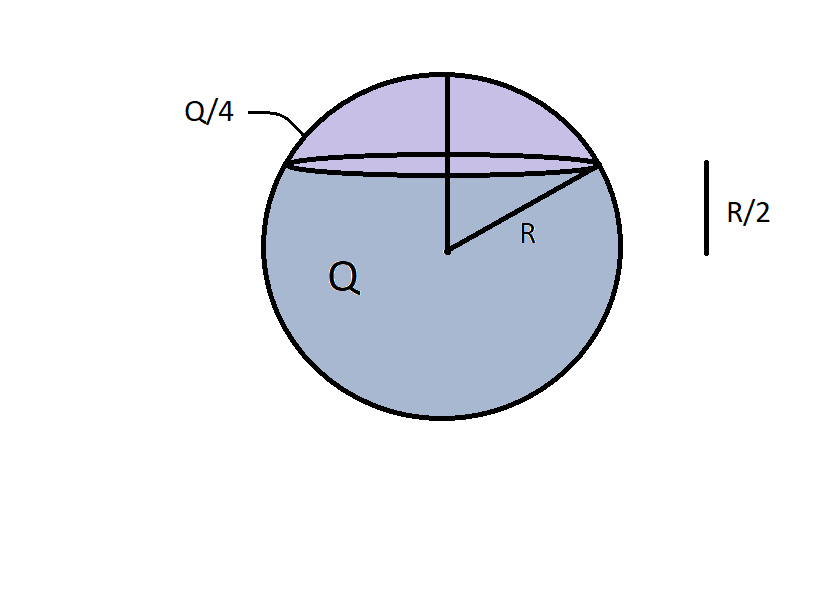

#### Now assume that a conducting ellipsoid is charged with a total charge $Q$. What is the charge on the surface above $\frac{R}{2}$?

#### Assume the radius in $\hat{z}$direction is still $R$ but in the $\left(x,y\right)$direction it is $\alpha R$, so the ellipsoid is defined by:

##                                                     $\frac{x^2 +y^2 }{\alpha^2 }+z^2 =R^2$                                             (1)

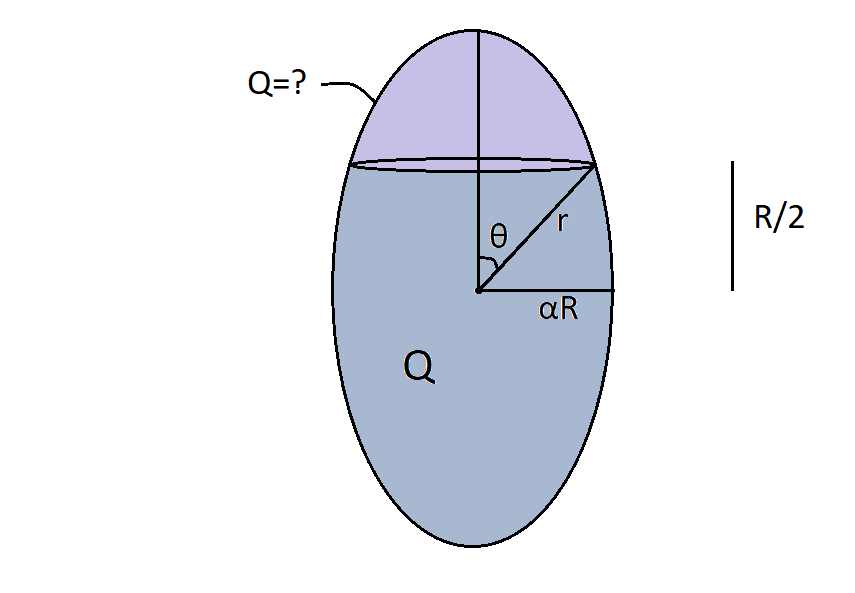

#### Plot $Q_{\textrm{up}}$for $\alpha =0\ldotp 1\ldotp \ldotp \ldotp 1$and $\alpha =1\ldotp \ldotp \ldotp 10$.

The problem requires us to find the charge in the region above R/2 of the ellipsoid given that the charge Q is uniformaly distributed over its surface. Thus we kniow that charge density($\sigma$) is constant on the ellipsoid and is given by 


$$\sigma =\frac{Q}{\textrm{Area}\;\textrm{of}\;\textrm{Ellipsoid}}$$


It is actually a spheroid since the radius in the x and y direction is the same and is $\alpha R$, where $\alpha$ is a parameter that varies the eccentricity, while in the z direction the radius is constant and is$R$.For the purpose of this report i will refer to  the shape in question as an ellipsoid.

We are provided with a special case of a sphere ($\alpha =1$) and the charge on the potion above $\frac{R}{2}$ for a sphere is $\frac{Q}{4}$. We need to find the charge for $\frac{R}{2}$ in the general case of an ellipsoid with a given $\alpha$.

### Method

My approach to solving this problem is as follows. We know that the charge density $\sigma$ for each ellipsoid having a certain $\alpha$ is constant over its surface. Thus if we know the area of the ellipsoid above $\frac{R}{2}$ and we are able to calculate the potential due to that part of the ellipsoid, we can use it to calculate the charge in that region.

So first of all we need to calculate the area of the ellipsoid above $\frac{R}{2}$. In spherical coordinates, we have the following relations with cartesian coordinates.


$$\begin{array}{l}
x=r*\sin \left(\theta \right)*\cos \left(\phi \right)\\
y=r*\sin \left(\theta \right)*\sin \left(\phi \right)\\
z=r*\cos \left(\theta \right)
\end{array}$$


Putting in eq(1) and simplifying, we end up with:

###                                                           $r\;=\frac{\alpha R}{\sqrt{\sin^2 \theta +\alpha^2 \cos^2 \theta }}$                                          (2)

Now from the second figure we can see that

                                                                                    
$$\cos \left(\theta \right)=\left(\frac{R}{2r}\right)$$


or

                                                                                        
$$r=\frac{R}{2\cos \left(\theta \right)}$$


putting in eq 2 we get

###                                                                  
$$\theta =\tan^{-1} \left(\alpha \sqrt{3}\right)$$


So when we are on the surface of the ellipsoid and the distance above the $\left(x,y\right)$plane is $\frac{R}{2}$, $\theta$ will be $\tan^{-1} \left(\alpha \sqrt{3}\right)$, where $\theta$ is measured from the z axis.

This is an important result as this will tell us the limits of integration for finding the area of ellipsoid above $\frac{R}{2}$.

Now we are in a position to calculate the area of the ellispoid in the required region. In spherical coordinates we have:


$$\textrm{SA}=\int_0^{2\pi } \int_0^{\tan^{-1} \left(\alpha \sqrt{3}\right)} r^2 \;\sin \theta \;d\theta \;d\phi$$


replacing the value of $r$ from eq 2


$$\textrm{SA}=\int_0^{2\pi } \int_0^{\tan^{-1} \left(\alpha \sqrt{3}\right)} \frac{\alpha^2 R^2 }{\sin^2 \theta +\alpha^2 \cos^2 \theta }\;\sin \theta \;d\theta \;d\phi$$


Solving this integral we get 3 seperate results depending on the value of $\alpha$.

If $\alpha >1$


$$\textrm{SA}=\frac{2\pi \alpha^2 R^2 }{\sqrt{\alpha^2 -1}}\left\lbrack \tan^{-1} \left(\sqrt{\alpha^2 -1}-\tan^{-1} \left(\sqrt{\alpha^2 -1}\cos \left(\tan^{-1} \left(\alpha \sqrt{3}\right)\right)\right)\right)\right\rbrack$$


if $0<\alpha <1$


$$\textrm{SA}=\frac{\pi \alpha^2 R^2 }{\sqrt{{1-\alpha }^2 }}\left\lbrack \ln \left(\frac{\left|\left(1-\alpha^2 \right)+\sqrt{1-\alpha^2 }\right|}{\left|\left(\alpha^2 -1\right)+\sqrt{1-\alpha^2 }\right|}\right)-\ln \left(\left(\frac{\left|\left(1-\alpha^2 \right)\cos \left(\tan^{-1} \left(\alpha \sqrt{3}\right)\right)+\sqrt{1-\alpha^2 }\right|}{\left|\left(\alpha^2 -1\right)\cos \left(\tan^{-1} \left(\alpha \sqrt{3}\right)\right)+\sqrt{1-\alpha^2 }\right|}\right.\right)\right\rbrack$$


and 

if $\alpha \;=1$


$$\textrm{SA}=\pi R^2$$


Once we have calculated the surface area of the required portion of the ellipsoid, we can move on to calculating its potential. SInce the charge density is uniform on the ellipsoid it will have a specific charge and a potential due to this charge in the desired portion, we can take away this surface area of the part of the ellipsoid and consider its potential seperately from the ellipsoid. We take this portion of the ellipsoid and construct a sphere having surface area equal to the portion of the ellipsoid above $\frac{R}{2}$. We do this because potential of a sphere is well defined and is easy to calculate if the surface charge density is known. The potential due to this sphere is given as:

### $V=\frac{r\sigma }{\varepsilon_0 }$                                                         (inside the sphere)

### $V=0$                                                           (far from the sphere)          

Where $r$ is the radius of the new sphere, $\sigma$ is the charge density and $\varepsilon_0$ is the permittivity of free space. This result has been taken from chapter 2 of reference 2. We use the above boundary conditions to apply Laplace's equation and to find the potential distribution around the sphere which gives us its electric field. Knowing the electric field we can then calculate the charge using Gauss's law and this will give us the charge on the portion of the ellipse above $\frac{R}{2}$. We then find the charge due to the portion of each ellipsoid above $\frac{R}{2}$ and plot it against the corresponding $\alpha$ values.

### Solution and Codes

I used the following code to test whether I can calculate the charge by first calculating the potential of a sphere knowing the boundary conditions and the charge density.

close all; clear all;

Q = 1e-6; % charge in Coulombs
R = 0.01; % radius of the sphere in meters

sigma = Q/(4*pi*R^2);   %charge density on a spherical surface with charge Q
eps = 8.8542e-12;       %permittivity of free space (F/m)
V_0 = (R*sigma)/eps;    %Constant potential inside a conducting sphere

N_steps = 500;

%I define the far away boundaries as 20 times the radius, the potential will be taken to be zero there
x_array = -20*R:1/N_steps:20*R; 
y_array = -20*R:1/N_steps:20*R;

N = size(x_array,2);
M = size(y_array,2);

V = zeros(M,N);

[X,Y] = meshgrid(x_array,y_array);

w = 1.7;
error = 1;

tic
count=0;

ErrorList=[];

while error > 0.001
    count = count + 1;
    for i = 1:N
        for j = 1:M
            if((x_array(i)^2+y_array(j)^2) <= R^2)
                V(i,j) = V_0;
            else
                if i==1
                    V_left = 0;
                else
                    V_left = V(i-1,j);
                end

                if i==N
                    V_right = 0;
                else
                    V_right = V(i+1,j);
                end

                if j == 1
                    V_bottom = 0;
                else
                    V_bottom = V(i,j-1);
                end

                if j == M
                    V_top = 0;
                else
                    V_top = V(i,j+1);
                end

                V(i,j) = w*(V_left+V_right+V_bottom+V_top)/4+(1-w)*V(i,j);
            end
            if((x_array(i)^2+y_array(j)^2) <= R^2)
                V(i,j) = V_0;
            end
        end
        
    end 

    ErrorMatrix = V-([zeros(N,1) V(:,1:N-1)]+[V(:,2:N) zeros(N,1)]+ [zeros(1,N); V(1:N-1,:)]+[ V(2:N,:); zeros(1,N)])/4;
    ErrorMatrix(:,(floor(N/2)-(N_steps/100)):(floor(N/2)+(N_steps/100)))=zeros(N,2*(N_steps/100)+1);
    ErrorMatrix((floor(M/2)-(N_steps/100)):(floor(M/2)+(N_steps/100)),:)=zeros(2*(N_steps/100)+1,M);
    error=sum(sum(abs(ErrorMatrix)));
    ErrorList=[ErrorList error];

%     if rem(count,1000)==1
%         figure(1); clf;
%         mesh(X,Y,V);
%         title(strcat('The potential after iteration=',num2str(count),' Error=',num2str(error)));
%         xlabel('y');ylabel('x');zlabel('V(x,y)');
%         pause(0.1);
%     end


end
toc

Elapsed time is 26.110723 seconds.


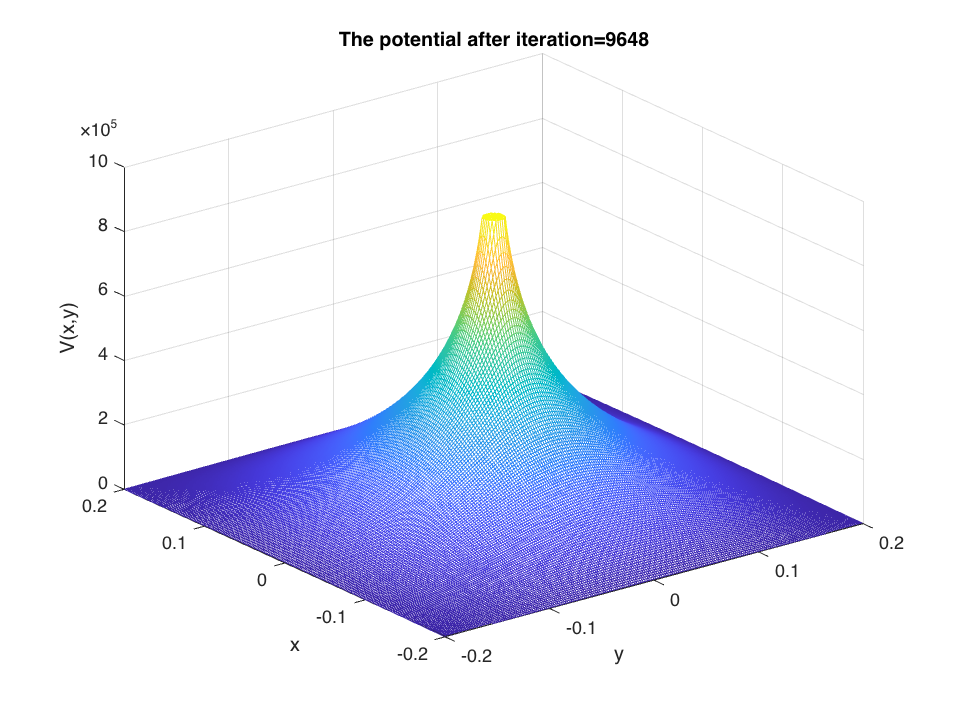


figure(1); clf;
mesh(X,Y,V);
title(strcat('The potential after iteration=',num2str(count)));
xlabel('y');ylabel('x');zlabel('V(x,y)');

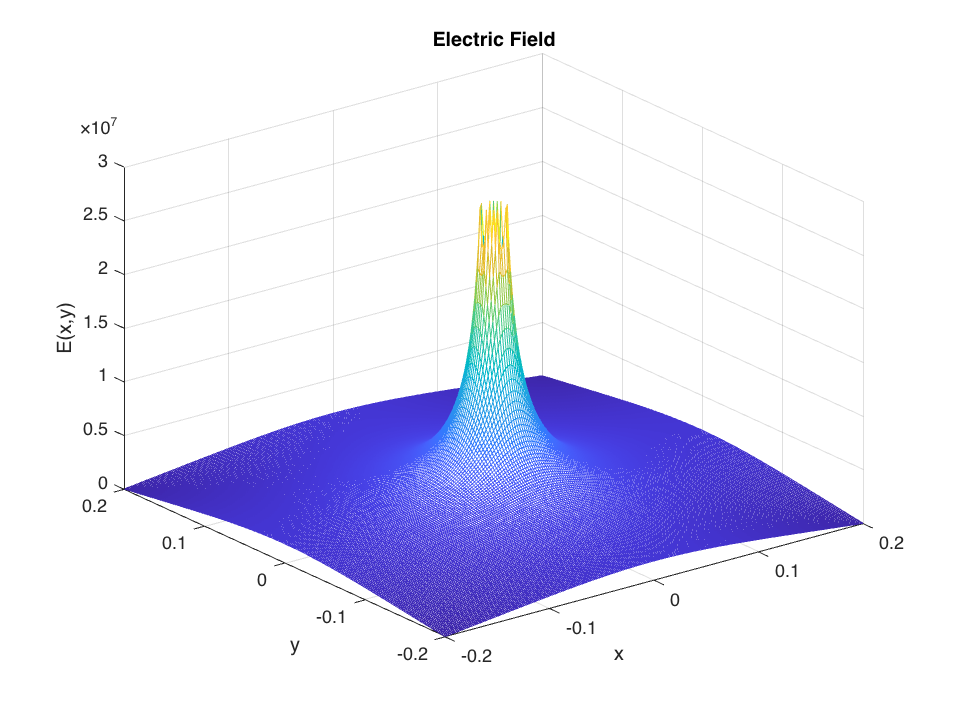



[FX,FY] = gradient(V,1/N_steps);

E_mat = (FX.^2 + FY.^2);

figure(2); clf;
mesh(X,Y,sqrt(E_mat));
title('Electric Field');
xlabel('x');ylabel('y');zlabel('E(x,y)');

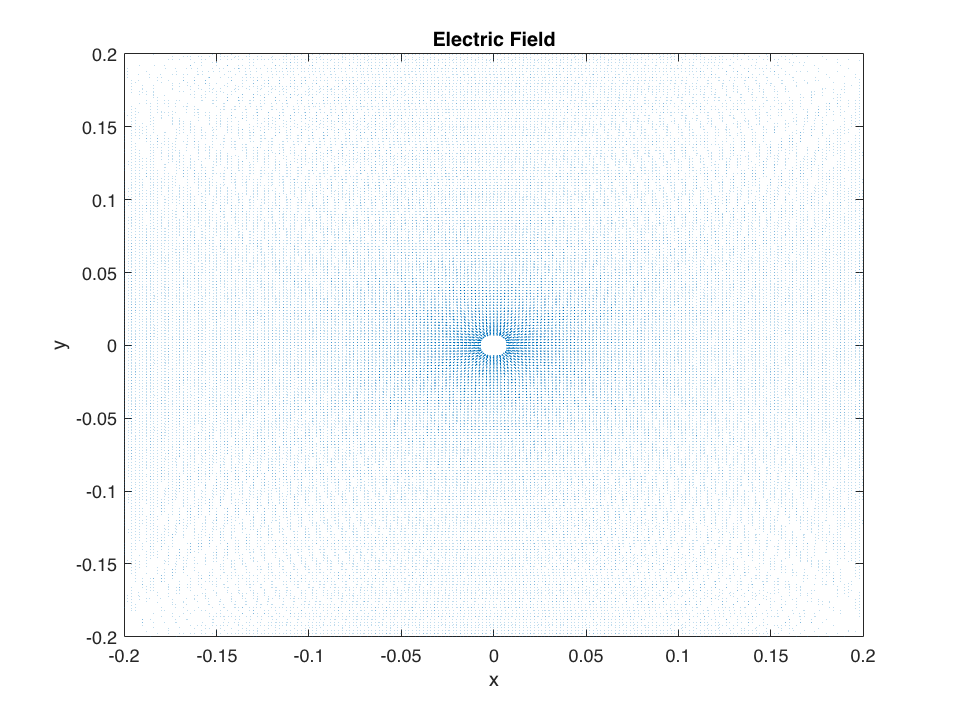


figure(3); clf;
quiver(X,Y,FX,FY);
title('Electric Field');
xlabel('x');ylabel('y');


E_mat = sqrt(E_mat);

Q_up = sum(sum(abs(E_mat))).*(1/N_steps)^2*eps/(3.2);

fprintf(strcat('The charge on the sphere is: ',num2str(Q_up), ' Coulombs'));

The charge on the sphere is:1.0165e-06 Coulombs

Thus i am able to calculate the charge of a sphere knowing the boundary conditions for the potential and the surface charge density. This test code gave me the correct result with an extra factor of 3.2 in every result of $Q_{\textrm{up}}$, considering it as an error I divided the final result by 3.2 to get the correct result in each case.

Next we extrapolate the above code according to the procedure described in the methods section. I have created a seperate function for calculating the area of the portion of the ellipsoid above $\frac{R}{2}$ using the three cases of the values $\alpha$ as described above.

close all; clear all;

Q = 1e-6; % charge in Coulombs
R = 0.01; % radius of the sphere in meters
eps = 8.8542e-12;  %permittivity of free space (F/m)

a1 = 0.1:0.1:3;
a2 = 4:1:20;
a = [a1 a2];        %Alpha values array
Q_vals = [];        %Q_up values will be stored here
area_vals = [];     %Area_up value will be stored here
Total_areas = [];   %Total surface areas of ellipsoid will be stored here
Qdensity_vals = []; %Charge density values will be stored here

tic
for var = 1:length(a)

For calculating the charge density of each ellipsoid I have used and simplified the equations for the surface area of a spheroid from reference 1 using $a=\alpha R$ and $c=R\;$. We first need to calculate the charge density of the ellipsoid so that we can use it to find the potential of the part of ellipsoid above $\frac{R}{2}$.

    if a(var) < 1
        
        surfArea = 2*pi*a(var)*R^2*(a(var)+acos(a(var))/sin(acos(a(var))));
        sigma = Q/(surfArea);%charge density on a ellipsoidal surface with charge Q
        
    elseif a(var) > 1
        
        surfArea = 2*pi*R^2*(a(var)^2+1/sin(acos(1/a(var)))*log(a(var)*(1+sin(acos(1/a(var))))));
        sigma = Q/(surfArea);%charge density on a ellipsoidal surface with charge Q
        
    elseif a(var) == 1
        
        surfArea = 4*pi*R^2;
        sigma = Q/(surfArea); %charge density on a spherical surface with charge Q
        
    end
    

Next we find the surface area for the top portion of the ellipsoid, turn it into a sphere with that same surface area, and find the radius $r$ of that new sphere. We do this using surfAreaEllipsoid function which takes in $\alpha$ and $R$values of the ellipsoid and gives us the surface area of the new sphere which is equal to the surface area of the top portion of the ellipsoid. It also returns the radius of the new sphere. 

[area, r] = surfAreaEllipsoid(a(var),R);

V_0 = (r*sigma)/eps;

N_steps = 100;


x_array = linspace(-20*r,20*r,N_steps);
y_array = linspace(-20*r,20*r,N_steps);

dx = (40*r)/N_steps;
dy = dx;

N = size(x_array,2);
M = size(y_array,2);

V = zeros(M,N);

[X,Y] = meshgrid(x_array,y_array);

w = 1.9;
error = 10;


count=0;

ErrorList=[];

while error > 0.001
    count = count + 1;
    for i = 1:N
        for j = 1:M
            if((x_array(i)^2+y_array(j)^2) <= r^2)
                V(i,j) = V_0;
            else
                if i==1
                    V_left = 0;
                else
                    V_left = V(i-1,j);
                end

                if i==N
                    V_right = 0;
                else
                    V_right = V(i+1,j);
                end

                if j == 1
                    V_bottom = 0;
                else
                    V_bottom = V(i,j-1);
                end

                if j == M
                    V_top = 0;
                else
                    V_top = V(i,j+1);
                end

                V(i,j) = w*(V_left+V_right+V_bottom+V_top)/4+(1-w)*V(i,j);
            end
            if((x_array(i)^2+y_array(j)^2) <= r^2)
                V(i,j) = V_0;
            end
        end
        
    end 

    ErrorMatrix = V-([zeros(N,1) V(:,1:N-1)]+[V(:,2:N) zeros(N,1)]+ [zeros(1,N); V(1:N-1,:)]+[ V(2:N,:); zeros(1,N)])/4;
    ErrorMatrix(:,(floor(N/2)-20):(floor(N/2)+20))=zeros(N,2*(20)+1);
    ErrorMatrix((floor(M/2)-(20)):(floor(M/2)+(20)),:)=zeros(2*(20)+1,M);
    error=sum(sum(abs(ErrorMatrix)));
    ErrorList=[ErrorList error];


end


[FX,FY] = gradient(V,dx);

E_mat = (FX.^2 + FY.^2);

E_mat = sqrt(E_mat);

Q_up = sum(sum(abs(E_mat))).*(dx*dy)*eps/(3.2);

Q_vals = [Q_vals Q_up];
area_vals = [area_vals area];
Total_areas = [Total_areas surfArea];
Qdensity_vals = [Qdensity_vals sigma];

end
toc

Elapsed time is 20.972920 seconds.


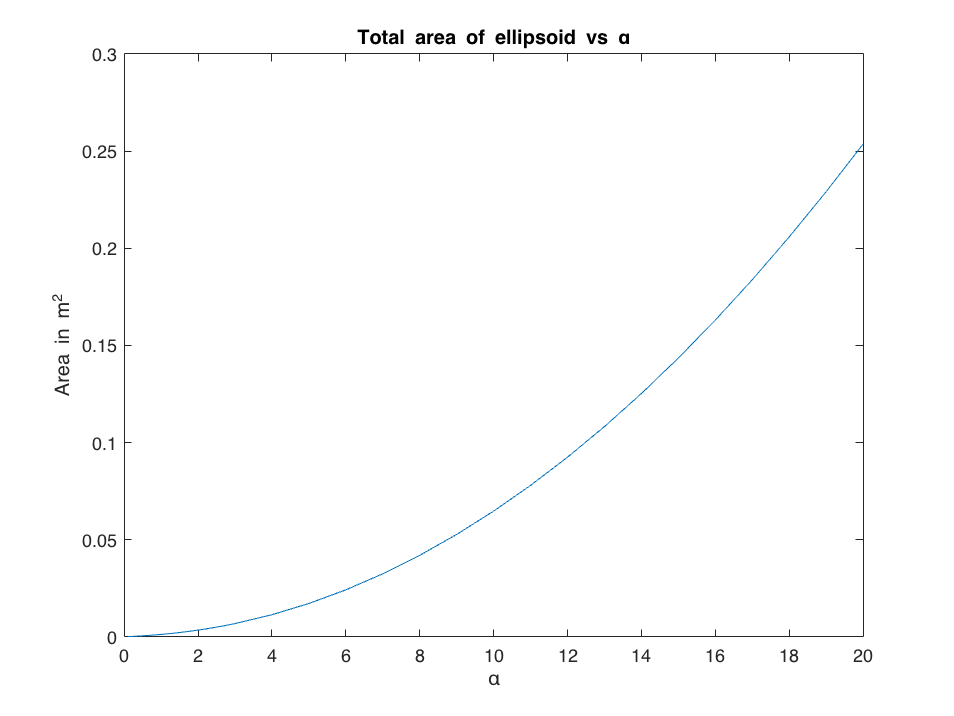


figure
plot(a,Total_areas);
ylabel('Area in m^{2}');
xlabel('\alpha');
title('Total area of ellipsoid vs \alpha');

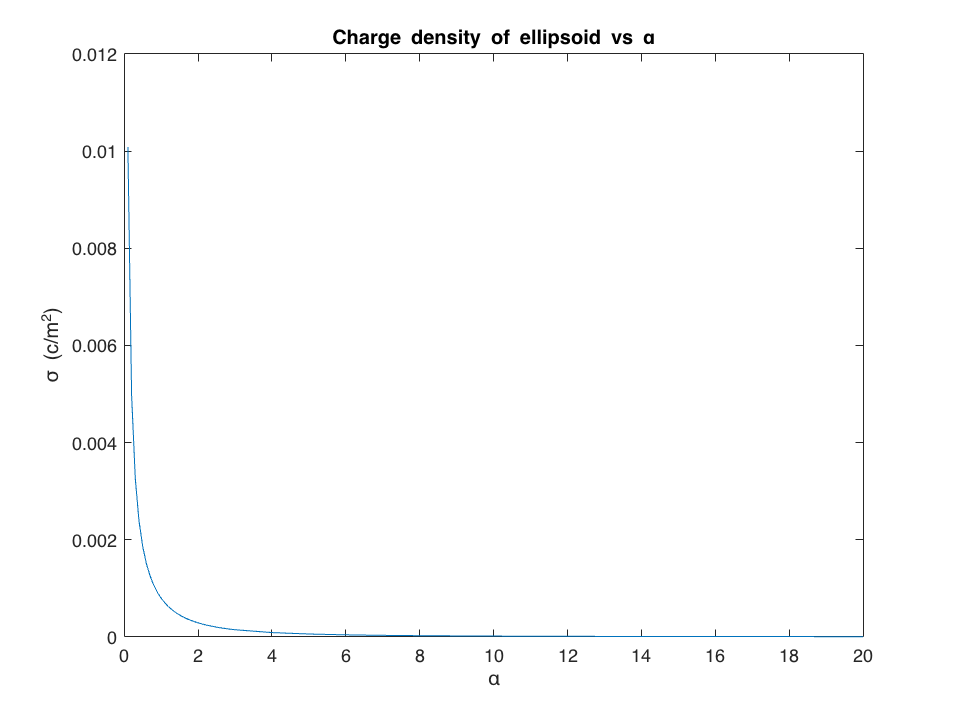


figure
plot(a,Qdensity_vals);
ylabel('\sigma (c/m^{2})');
xlabel('\alpha');
title('Charge density of ellipsoid vs \alpha');

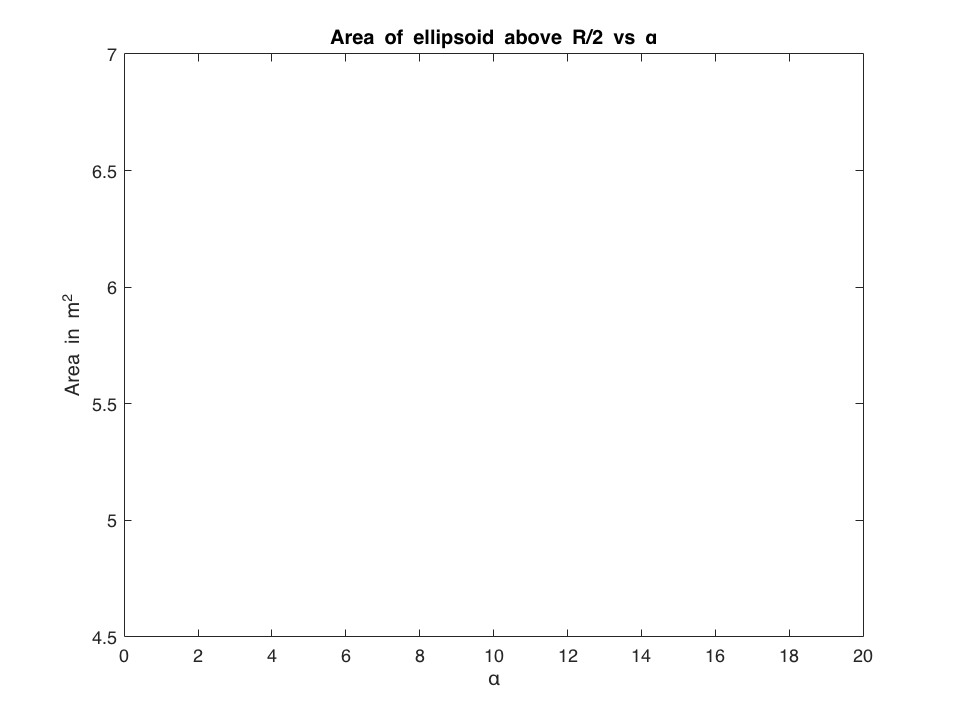


figure

ghj = area_vals/Total_areas*100;
plot(a,ghj);
ylabel('Area in m^{2}');
xlabel('\alpha');
title('Area of ellipsoid above R/2 vs \alpha');

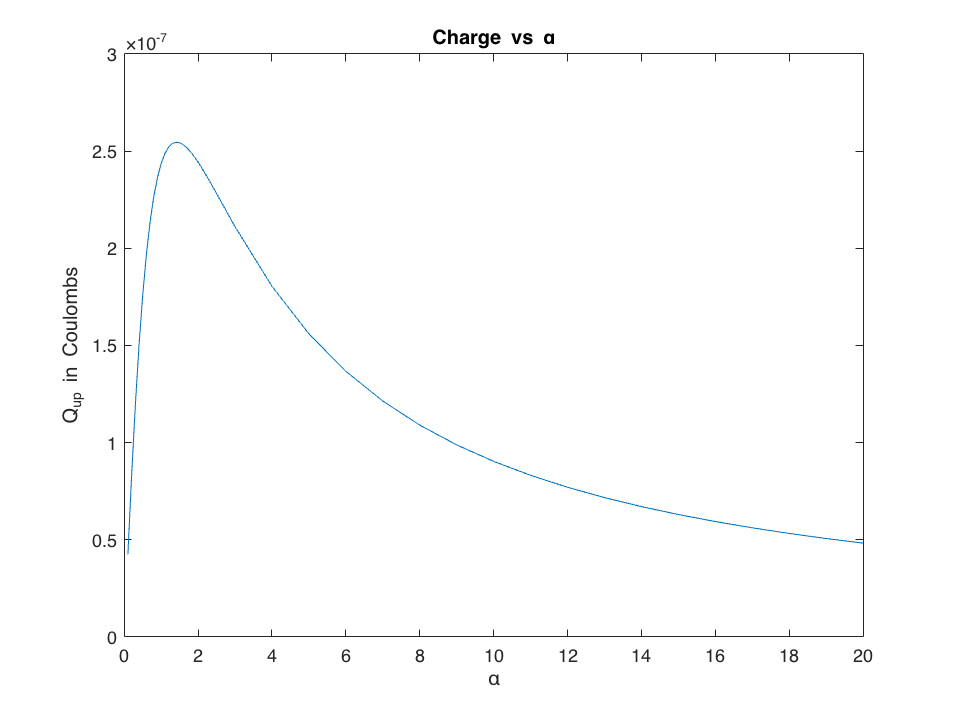


figure
plot(a,Q_vals);
xlabel('\alpha');
ylabel('Q_{up} in Coulombs');
title('Charge vs \alpha');

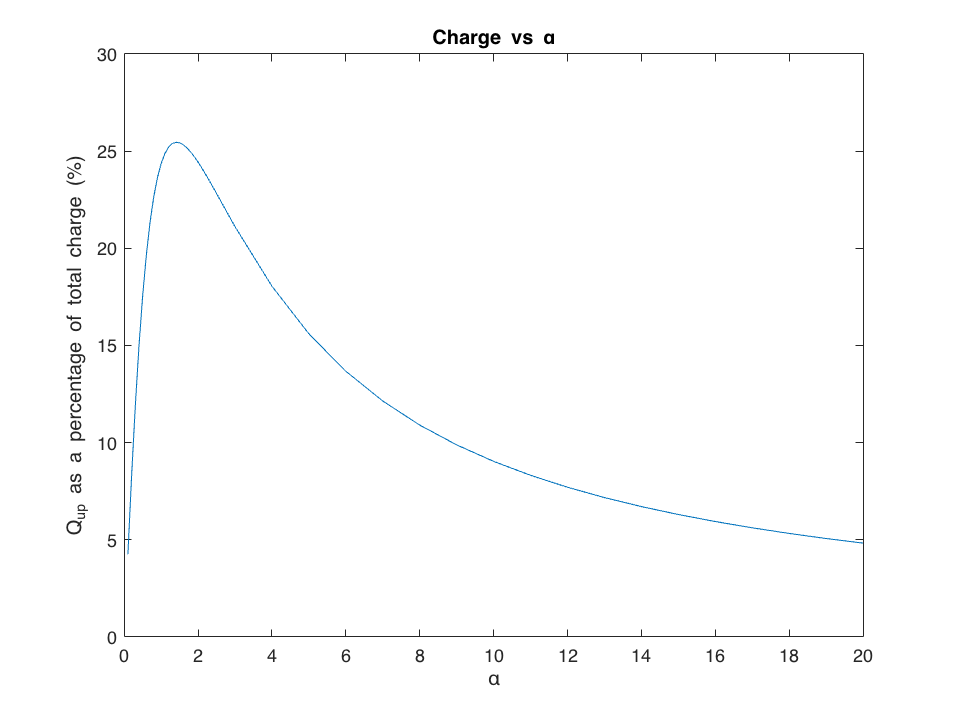


figure
plot(a,(Q_vals./Q).*100);
xlabel('\alpha');
ylabel('Q_{up} as a percentage of total charge (%)');
title('Charge vs \alpha');

function [SA, r_new] = surfAreaEllipsoid(a,R)

%Takes alpha value and the radius in the z direction as input and
%gives the surface area of the top of the ellipsoid
%Takes the portion above R/2, where R is the radius in the z direction
%Also gives the radius of the sphere of the resulting surface area

    if a < 1

        SA = (1*pi*a^2*R^2)/sqrt(1-a^2)*(-log(abs((1-a^2)*cos(atan(a*sqrt(3)...
            ))+sqrt(1-a^2))/abs((a^2-1)*cos(atan(a*sqrt(3)))+sqrt(1-a^2)))+...
            log(abs((1-a^2)+sqrt(1-a^2))/abs((a^2-1)+sqrt(1-a^2))));

    elseif a > 1

        SA = (2*pi*a^2*R^2)/sqrt(a^2-1)*(atan(sqrt(a^2-1))-atan(sqrt(a^2-1)...
            *cos(atan(a*sqrt(3)))));

    elseif a == 1

        SA = 1*pi*R^2;

    else

        SA = 0;
    
    end
    
    r_new = sqrt(SA/(4*pi));
    
end


### Results and Discussion

 We can see from the last graph the behaviour of the portion of charge above $\frac{R}{2}$ of an ellipsoid compared with its $\alpha$value. We see that when $\alpha$ is much less then 1 or in other words we have an elongated ellipdoid also known as a prolate spheroid, the charge on the portion of the ellipdoid above $\frac{R}{2}$is quite less, much less then $\frac{1}{4}\textrm{th}$ as in the spherical case. As we increase $\alpha$ and move towards a spherical shape, the charge in the top portion of the ellipsoid starts increasing, it reaches $\frac{1}{4}\textrm{th}$ of the total charge when the ellipoid becomes a sphere at $\alpha =1$. Upon increasing $\alpha$ further with values greater then 1 we see that $Q_{\textrm{up}}$ increases a little till $\alpha =1\ldotp 4$and then starts decreasing. with $\alpha$ values greater then 1 we get a squashed ellipsoid also known as an oblate spheroid. Upon further increasing $\alpha$, $Q_{\textrm{up}}$keeps decreasing and starts approaching 0 at large values of $\alpha$. I have also plotted the area of the top portion of the ellipsoid against $\alpha$, we see that the area in the top portion increases fairly linearly with $\alpha$ which makes sense as we squash the ellipsoid more and more we expect to get more surface area in the top portion. The decrease in $Q_{\textrm{up}}$at larger values of $\alpha$ can be understood by taking a look at the graphs showing the total area of the ellipsoid and $\sigma$ values. At large $\alpha$, $\sigma$ is very low due to the fact that the total surface area is increasing almost exponentially while the total charge is constant. Since the charge density is decreasing, it makes sense that the charge in the top portion of the ellipsoid will also be decreasing. But the story at low $\alpha$ values is more interesting where $Q_{\textrm{up}}$increases with $\alpha$ even though the charge density is decreasing.

To conclude, in this project I have applied a new approach (to my knowledge) to calculate the charge on the portion of an ellipsoid by knowing the charge density and the boundary conditions for the potential. I take the portion of the ellipsoid, turn it into a sphere and then perform the analysis to find the charge. This bypasses the need to calculate the potential due to the ellipsoid and to then find the effective potential of the top portion to calculate the charge. Instead, using this approach we can apply the familiar analysis of the potential of a sphere to analyse the charge on a portion of an ellipsoid.

### References

- *Ellipsoid*. (n.d.). PLANETCALC. [https://planetcalc.com/149/](https://planetcalc.com/149/)

- Griffiths, D. J. (2017). *Introduction to Electrodynamics* (4th ed.). Cambridge University Press.